## Serie de tiempo

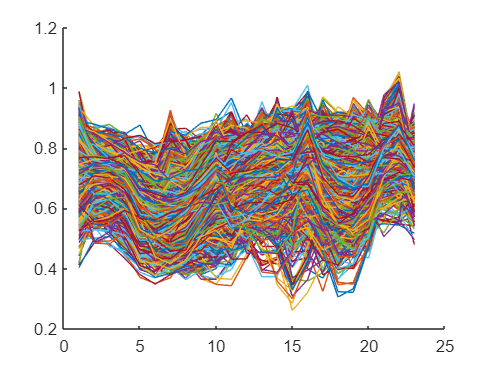

% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

% indxs=find(info_hdf.anio==2022);
% datos=arr_ndvi_sgf(:,:,indxs);

% Esta variable se utiliza solo para tepezintla
datos=arr_ndvi_sgf;

[alto,ancho,~]=size(datos);
figure; 
hold on
temp_Mediana=[];
temp_Mean=[];
temp_Mode=[];
temp_Range=[];
temp_Desv=[];
temp_Min=[];
temp_Max=[];
temp_Std=[];
temp_Mad=[];
temp_valor=[];
id=1;
for i=1:alto
     for j=1:ancho
        if(study_area(i,j)==1)
            serie = reshape(datos(i,j,:),[],1);
            plot(serie)
            temp_Mediana(id) =median(serie);
            temp_Mean(id)=mean(serie);
            temp_Mode(id)=mode(serie);
            temp_Range(id)=range(serie);
            temp_Desv(id)=std(serie);
            temp_Min(id)=min(serie);
            temp_Max(id)=max(serie);
            temp_Mad(id)=mad(serie);
            temp_valor(id)=0;
            id=id+1;
        end
    end
end
hold off


tab_data=table( temp_Mediana',temp_Mean',temp_Mode',temp_Range',temp_Desv',temp_Min',temp_Max',temp_Mad',temp_valor',VariableNames=["Mediana","Promedio","Moda","Rango","Desviacion","Minimos","Maximos","Mad","Valor"]);

data_tab_function=f_aplica_formulas(arr_ndvi_sgf,study_area,1)

data_tab_function = 4251×9 table
    Mediana    Promedio     Moda       Rango     Desviacion    Minimos    Maximos      Mad       Valor
    _______    ________    _______    _______    __________    _______    _______    ________    _____

    0.65988     0.6237     0.45719    0.29609     0.097277     0.45719    0.75328    0.083042      1  
    0.66324    0.61953     0.45546    0.32912     0.099648     0.45546    0.78458    0.083797      1  
    0.73184    0.71625      0.4979    0.36458     0.098571      0.4979    0.86247    0.075809      1  
    0.73853    0.71128     0.53004    0.33861     0.094316     0.53004    0.86866     0.07508      1  
    0.68014    0.63886     0.45846    0.29

Salvar los datos

writetable(tab_data,'M.xls')


Leer los datos almacenados

dir_data_procces="C:\Users\SALAS\Desktop\DATA_NARANJAS\PROCESS\";
file_read=["01_Cultivo_1.xls","01_Cultivo_3.xls","02_Bosque.xls","02_CIUDAD.xls","02_Selva.xls"];
t_positiv_1=readtable(dir_data_procces+file_read(1));
t_positiv_2=readtable(dir_data_procces+file_read(2));
t_negativ_1=readtable(dir_data_procces+file_read(3));
t_negativ_2=readtable(dir_data_procces+file_read(4));
t_negativ_3=readtable(dir_data_procces+file_read(5));

Union de valores

data_positiv=t_positiv_2;

data_negativ=[t_negativ_1;t_negativ_2;t_negativ_3];
data_all=[data_negativ;data_positiv];


[a,b]=size(data_positiv);
[c,d]=size(data_negativ);

data_learn=[data_positiv(1:(a/2), :); data_negativ(1:(c/2),:)];
x=int16(a/2);
y=int16(c/2);
data_test=[data_positiv(x:a,:);data_negativ(y:c,:)];




Ingresando los datos tratados


data_tepezintla=tab_data(:,1:8);

## Implementacón de las redes neuronales 

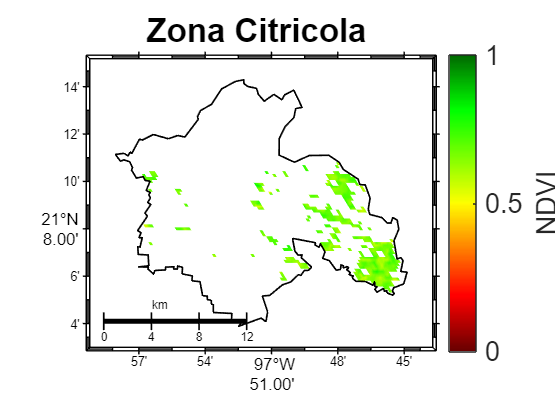

class_result=model_entrenado.predictFcn(data_tepezintla);

area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);
area_clasificada=arr_ndvi_sgf;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),"Zona Citricola ",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

## **Creando mascara con los resultados**

[t_tep,~]=size(data_tepezintla);
[alto,ancho,~]=size(arr_ndvi_sgf);

ind_temp=1;
mask_tep=zeros(alto,ancho);

for i=1:alto
     for j=1:ancho
        if(study_area(i,j)==1)
            mask_tep(i,j) = class_result(ind_temp);
            ind_temp=ind_temp+1;
        end
    end
end


Aplicando mascara

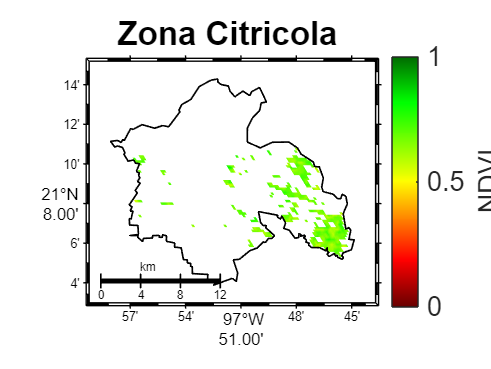

area_clasificada=arr_ndvi_sgf;
area_clasificada(mask_tep==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),"Zona Citricola ",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

% Ejemplo de datos
x = [1, 2, 3, 4, 5];
y = [2, 4, 5, 4, 5];

% Calcular la matriz de correlación (correlación de Pearson)
correlation_matrix = corrcoef(x, y);

% La correlación de Pearson es el elemento en la posición (1, 2) o (2, 1) de la matriz
pearson_correlation = correlation_matrix(1, 2);

% Mostrar el resultado
disp(['Correlación de Pearson: ', num2str(pearson_correlation)]);

Correlación de Pearson: 0.7746
